Lecture 12 Matlab  

Let x (t) = cos (2*pi*100*time) + cos (2*pi*400*time). Find x (n) by sampling x(t) with 

fs = 1000 Hz to generate N = 1000 samples.

(a) Plot x(t).

(b) Find X(f); plot |X(f)| and angle(X(f)). Use M = 4000.

(c) Find output y1(t) by filtering x(t) with a 4th order low pass Butterworth filter with

cutoff at fc  = 200 Hz.

(d) Find Y1(f); plot |Y1(f)| and angle(Y1(f)). Use M = 4000.

(e) Find output y2(t) by filtering x(t) with a 4th order high pass Butterworth filter with

cutoff at fc  = 200 Hz.

(f) Find Y2(f); plot |Y2(f)| and angle(Y2(f)). Use M = 4000.

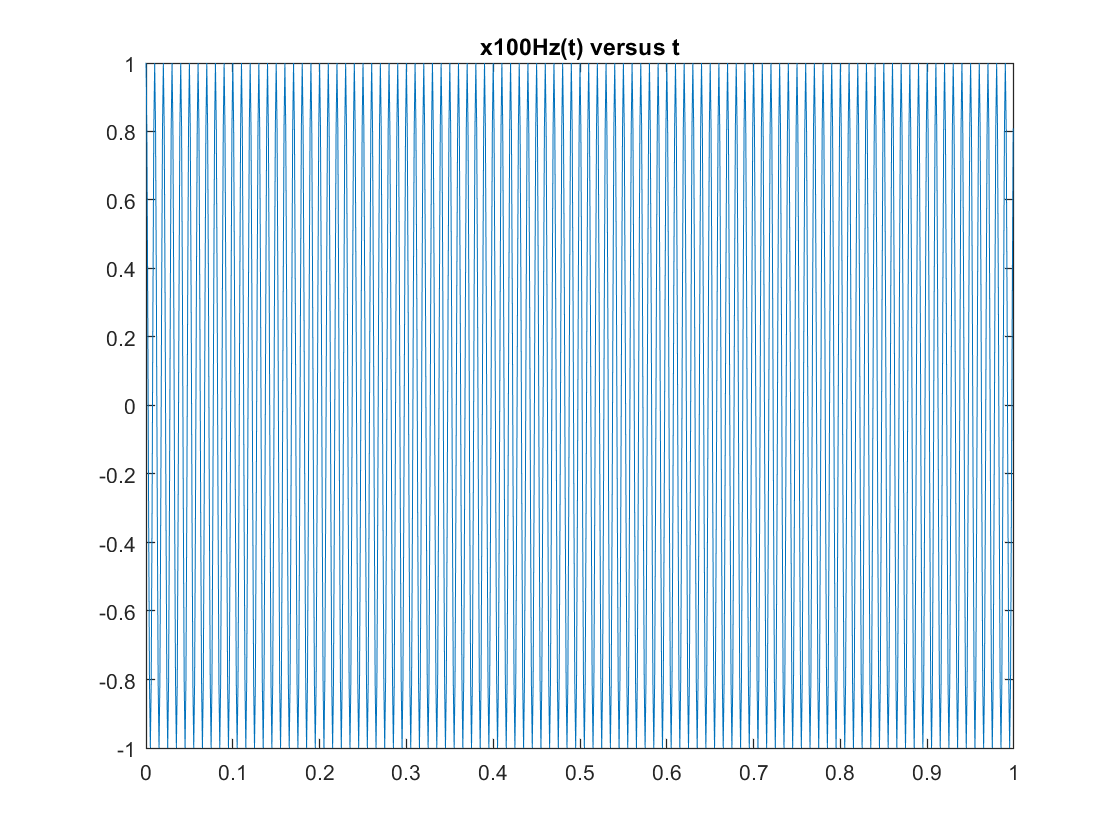

% Let x (t) = cos (2*pi*100*time) + cos (2*pi*400*time). Find x (n) by sampling x(t) with 
% fs = 1000 Hz to generate N = 1000 samples.

% (a) Plot x(t).

fs = 1000; ts = 1/fs; N = 1000; time = 0: ts : (N-1)*ts; % Generate time
%
f1 = 100.0; f2 = 400.0;
x100Hz = cos(2*pi*f1*time);
x400Hz =  cos(2*pi*f2*time);
x = x100Hz + x400Hz;
plot (time, x100Hz); title ('x100Hz(t) versus t')

% Plot for the time interval 0 to (N1-1)*ts
N1 = 101

N1 = 101

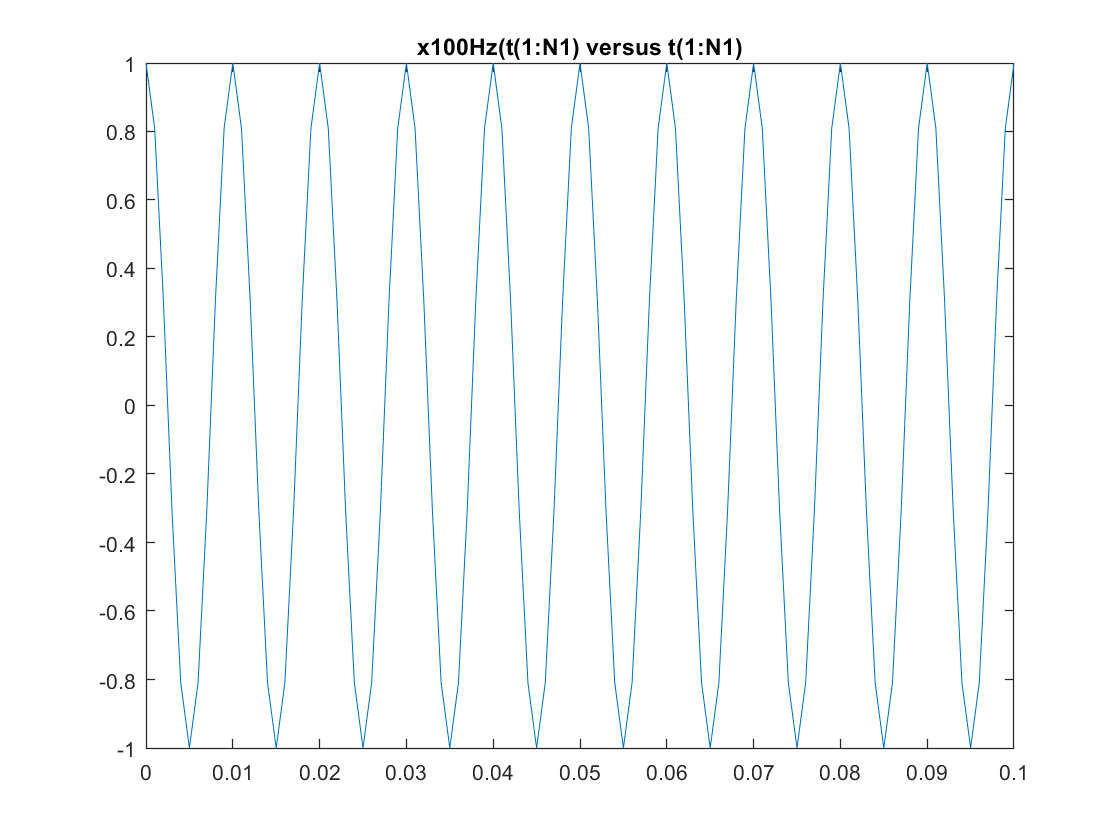

plot (time(1:N1), x100Hz(1:N1)); title ('x100Hz(t(1:N1) versus t(1:N1)')

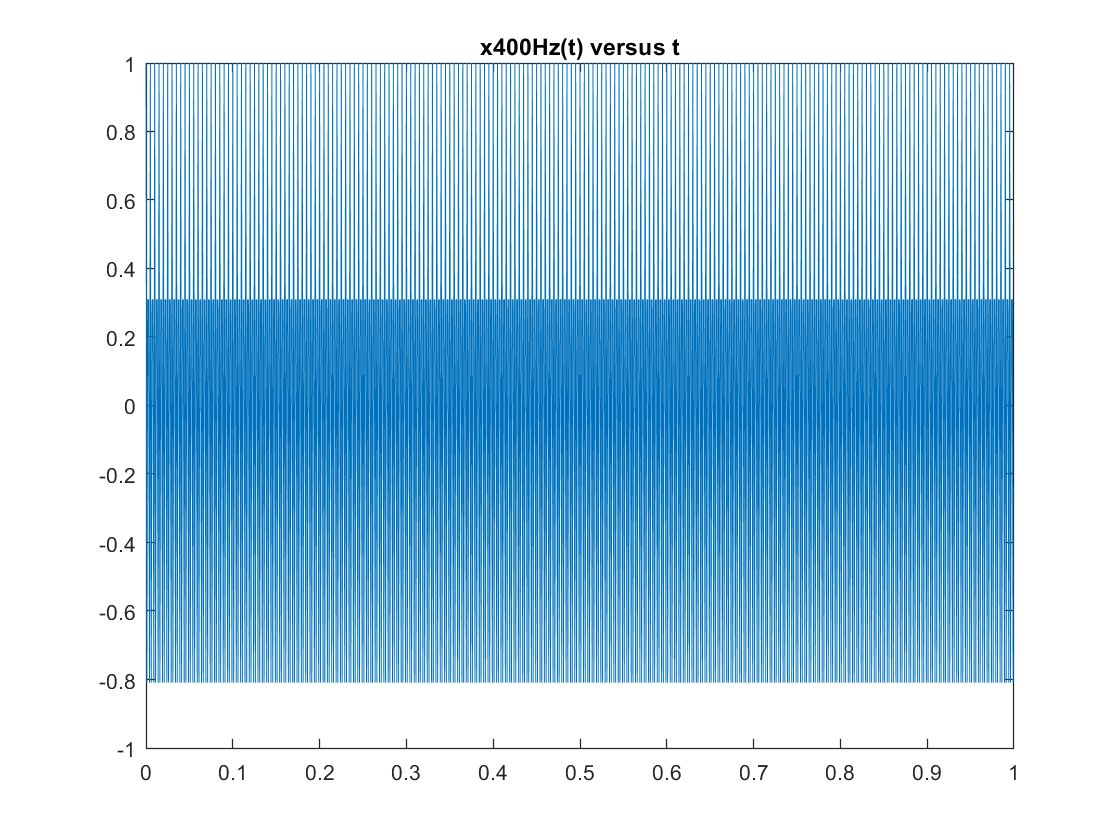

plot (time, x400Hz); title ('x400Hz(t) versus t')

N1 = 101

N1 = 101

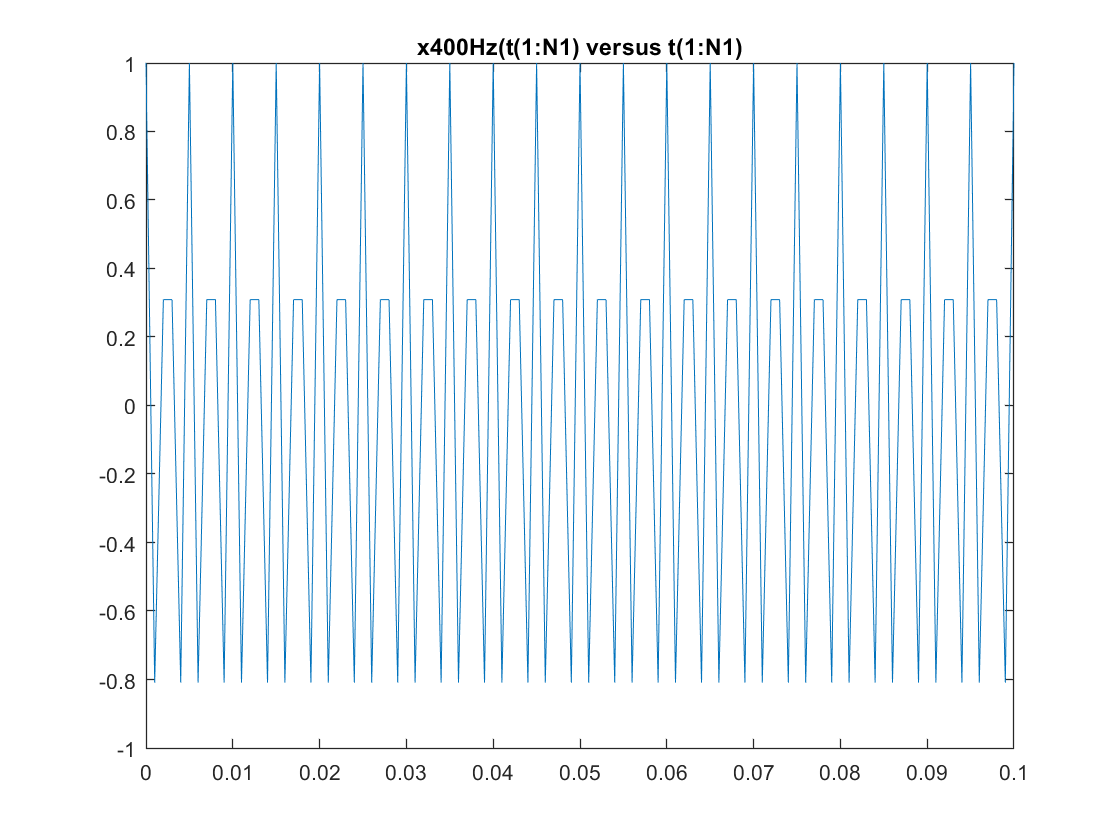

plot (time(1:N1), x400Hz(1:N1)); title ('x400Hz(t(1:N1) versus t(1:N1)')

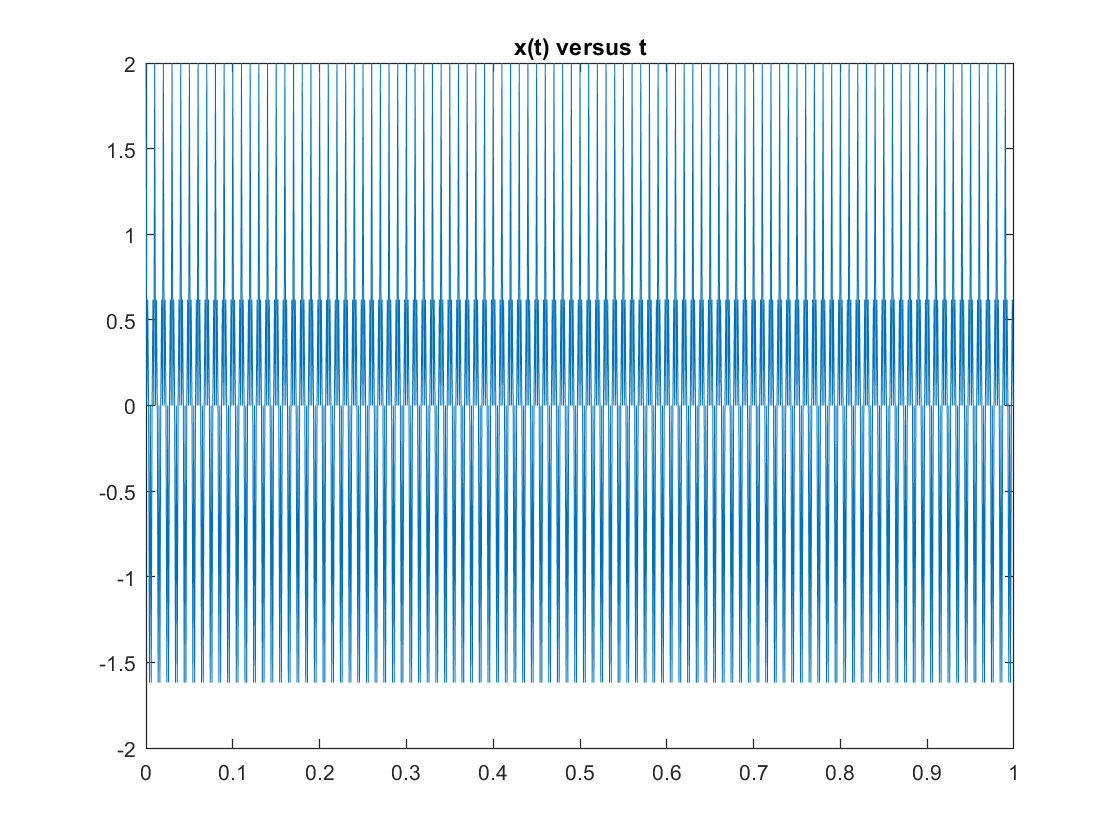

plot (time, x); title ('x(t) versus t')

% Plot for the time interval 0 to (N1-1)*ts
N1 = 101

N1 = 101

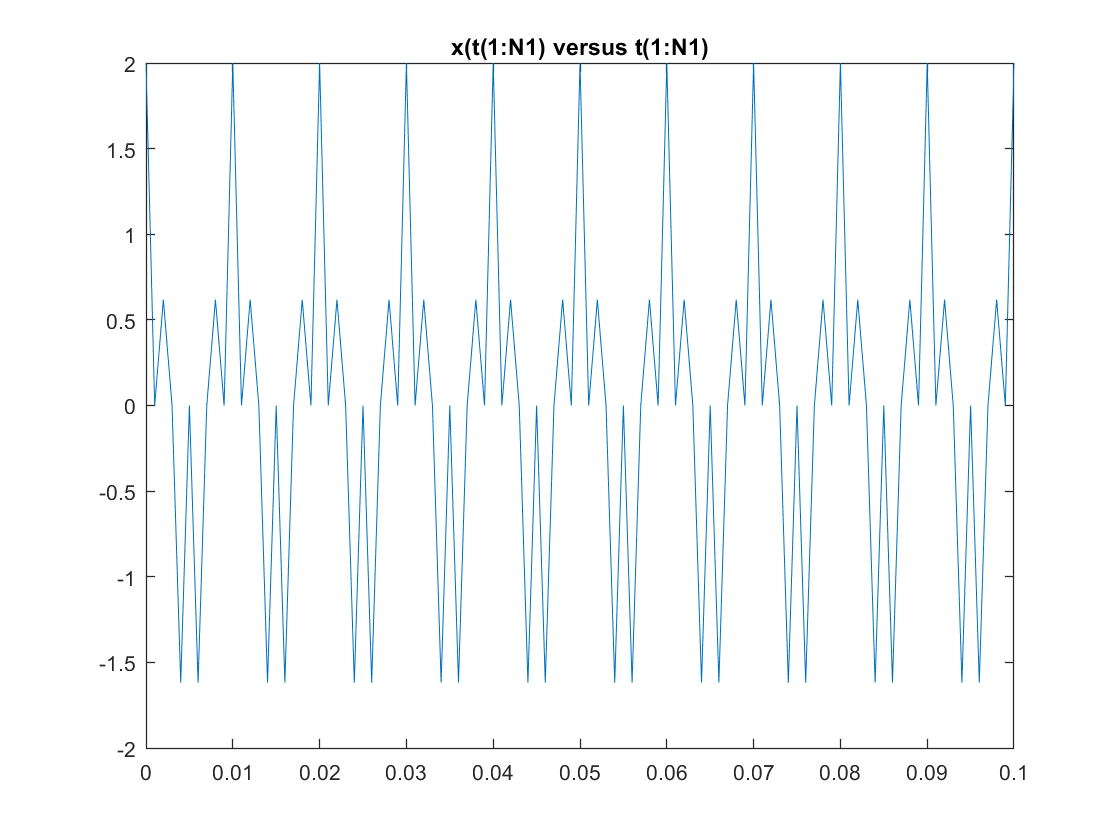

plot (time(1:N1), x(1:N1)); title ('x(t(1:N1) versus t(1:N1)')

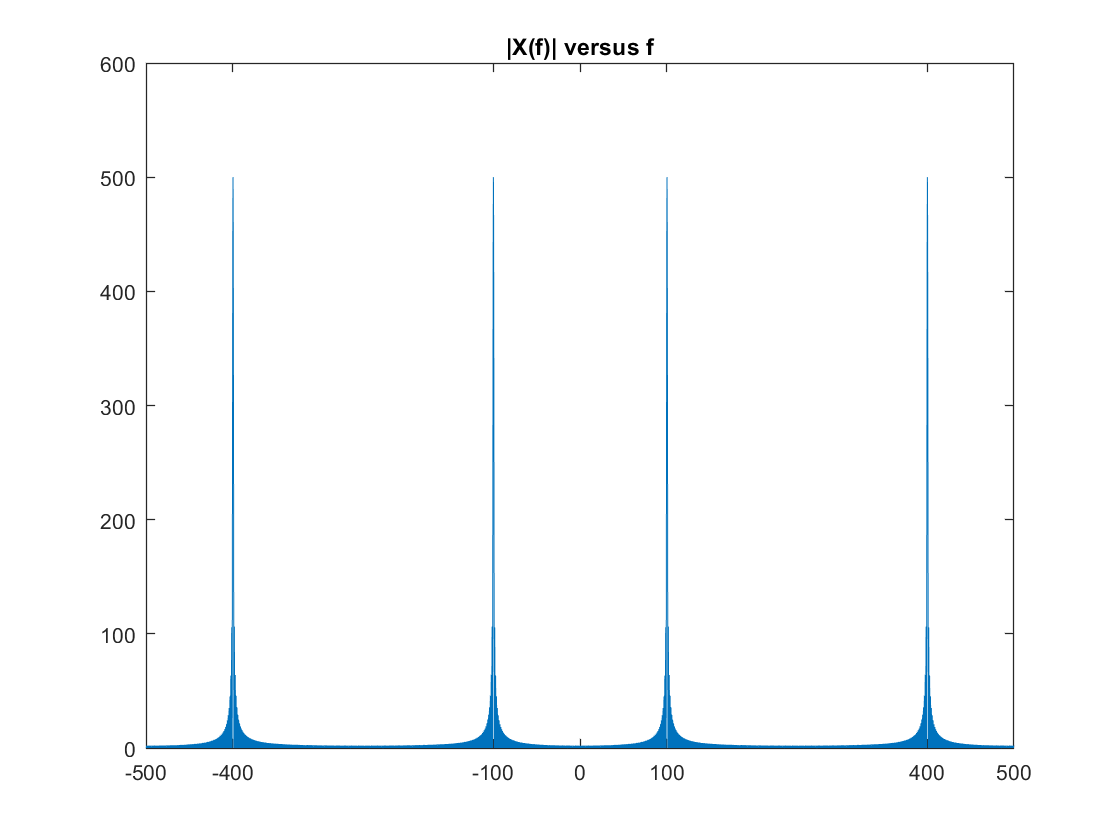

% (b) Find X(f); plot |X(f)| and angle(X(f)). Use M = 4000.
M = 4000;
xfftsh = fftshift(fft(x,M));
%
df = fs/M;
freq = -(fs/2 - df):df:fs/2;
plot(freq, abs(xfftsh)); 
ax = gca;
ax.XTick = [-500 -400 -100 0 100 400 500];
title('|X(f)| versus f')

%

% (c) Find output y1(t) by filtering x(t) with a 4th order low pass Butterworth filter with
% cutoff at fc  = 200 Hz.
% (d) Find Y1(f); plot |Y1(f)| and angle(Y1(f)). Use M = 4000.
% Matlab normalized frequency wn = 1 = fs/2.
% 200 Hz cut off is equal to wn = 0.4 for fs = 1000 Hz or fs/2 = 500 Hz.
% Find the filter coefficients [b, a].
wn = 0.4;
[b, a] = butter(4,wn,'low')

b =     0.0466    0.1863    0.2795    0.1863    0.0466


a =     1.0000   -0.7821    0.6800   -0.1827    0.0301


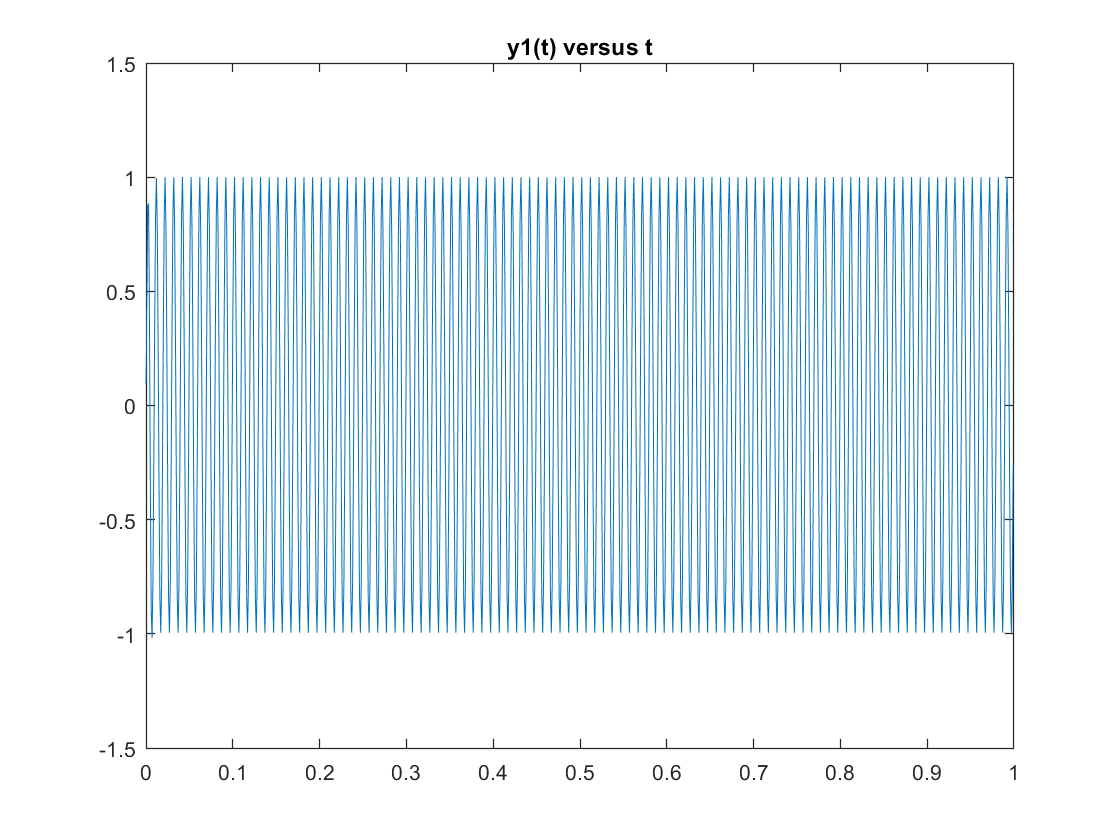

y1 = filter(b,a,x);
plot(time,y1);
title('y1(t) versus t')

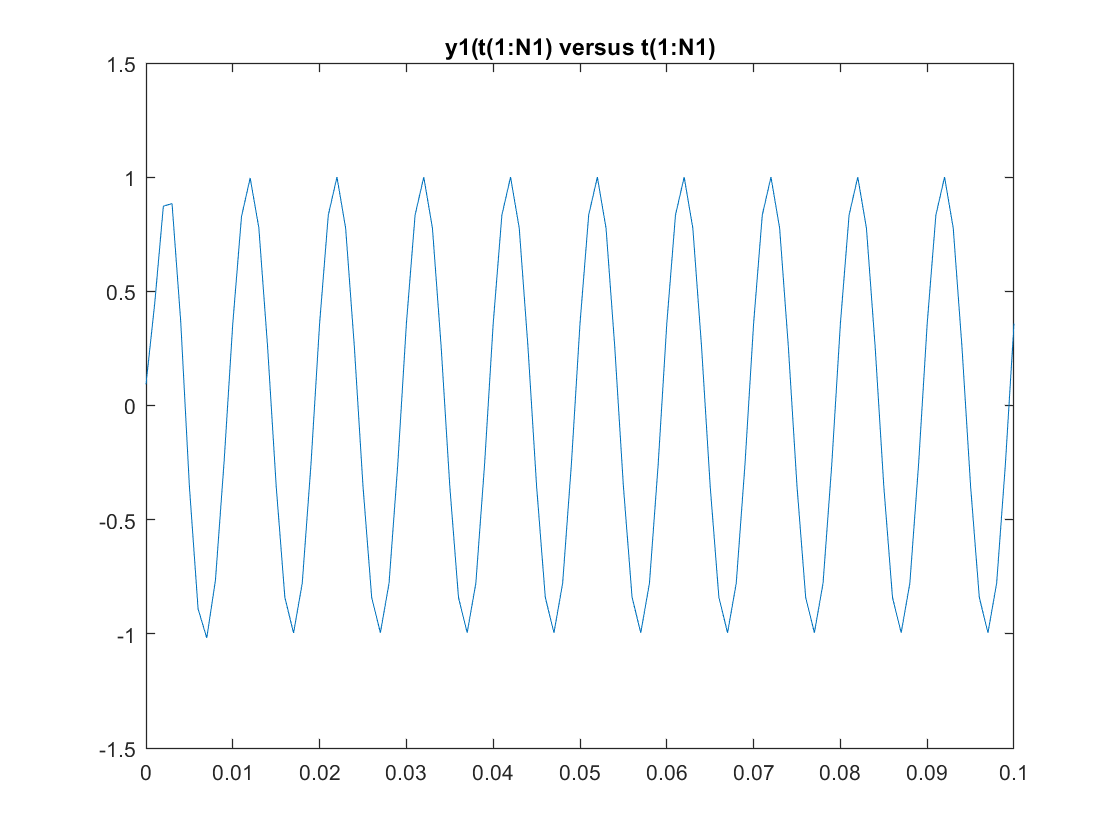

plot (time(1:N1), y1(1:N1)); title ('y1(t(1:N1) versus t(1:N1)')

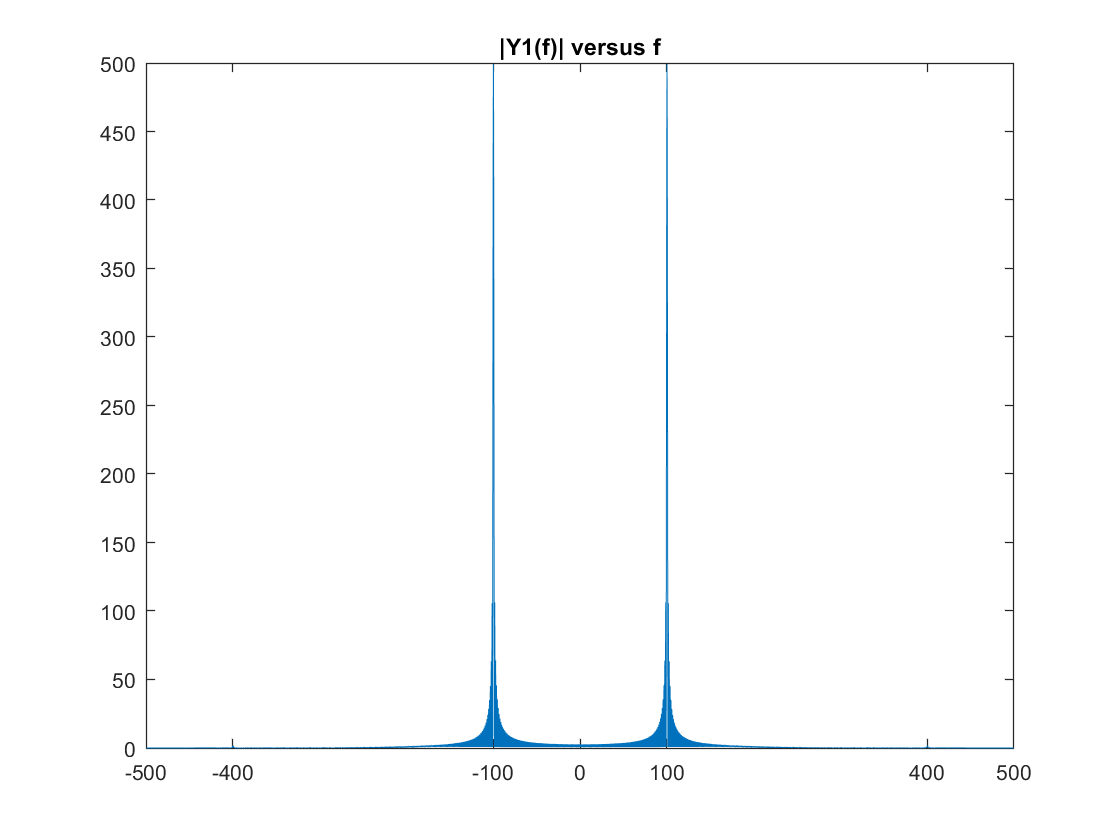

y1fftsh = fftshift(fft(y1,M));
plot(freq, abs(y1fftsh)); 
ax = gca;
ax.XTick = [-500 -400 -100 0 100 400 500];
title('|Y1(f)| versus f')

% (e) Find output y2(t) by filtering x(t) with a 4th order high pass Butterworth filter with
% cutoff at fc  = 200 Hz.
% (d) Find Y1(f); plot |Y1(f)| and angle(Y1(f)). Use M = 4000.
% Matlab normalized frequency wn = 1 = fs/2.
% 200 Hz cut off is equal to wn = 0.4 for fs = 1000 Hz or fs/2 = 500 Hz.
% Find the filter coefficients [b, a].
wn = 0.4;
[b, a] = butter(4,wn,'high')

b =     0.1672   -0.6687    1.0031   -0.6687    0.1672


a =     1.0000   -0.7821    0.6800   -0.1827    0.0301


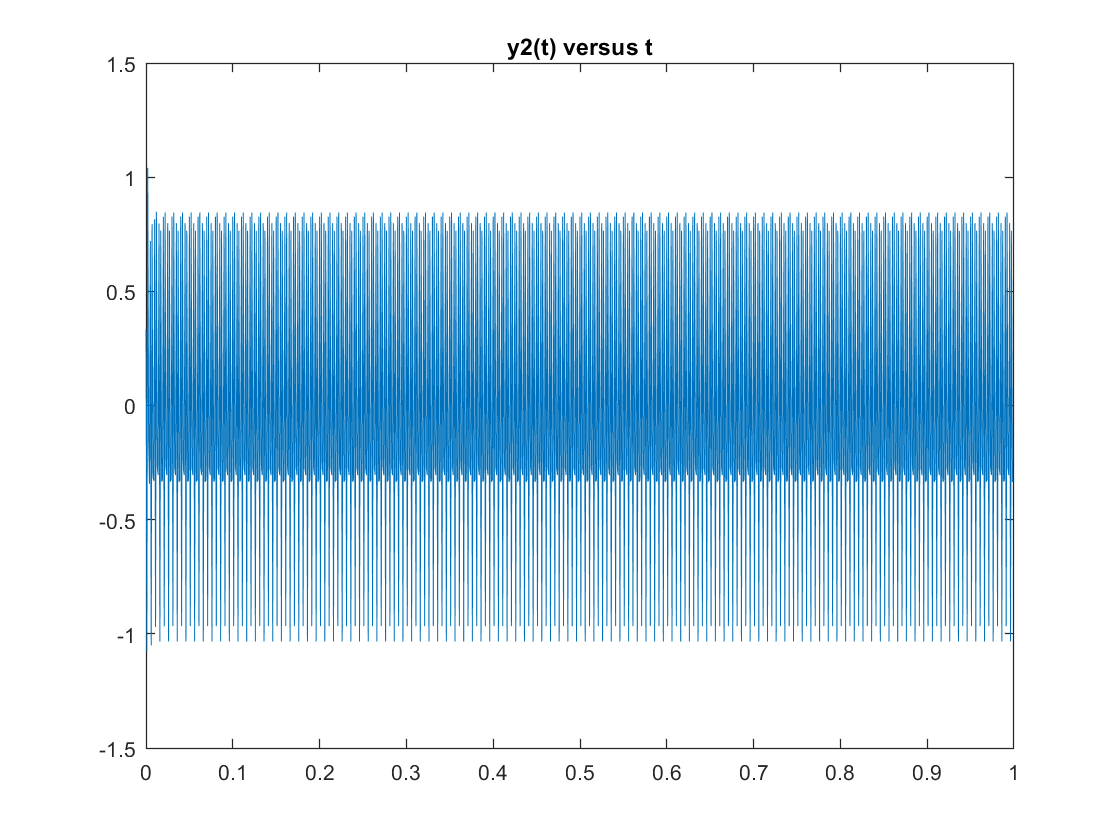

y2 = filter(b,a,x);
plot(time,y2);
title('y2(t) versus t')

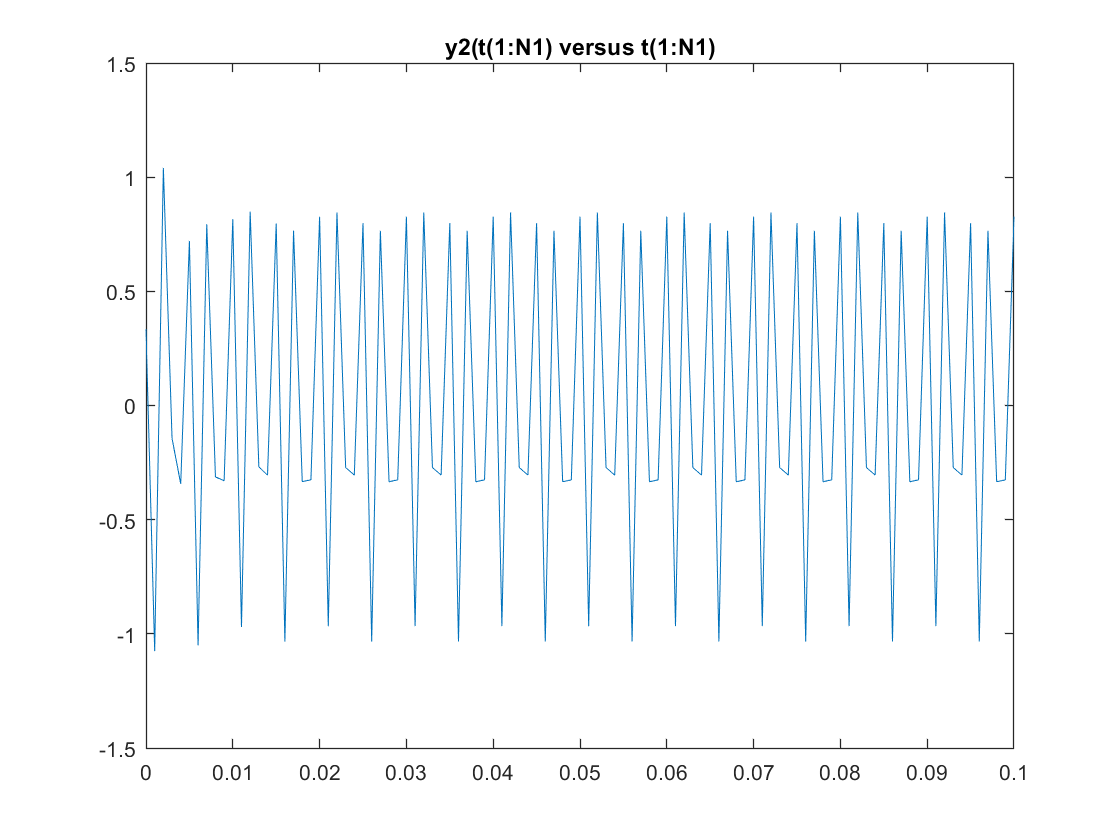

plot (time(1:N1), y2(1:N1)); title ('y2(t(1:N1) versus t(1:N1)')

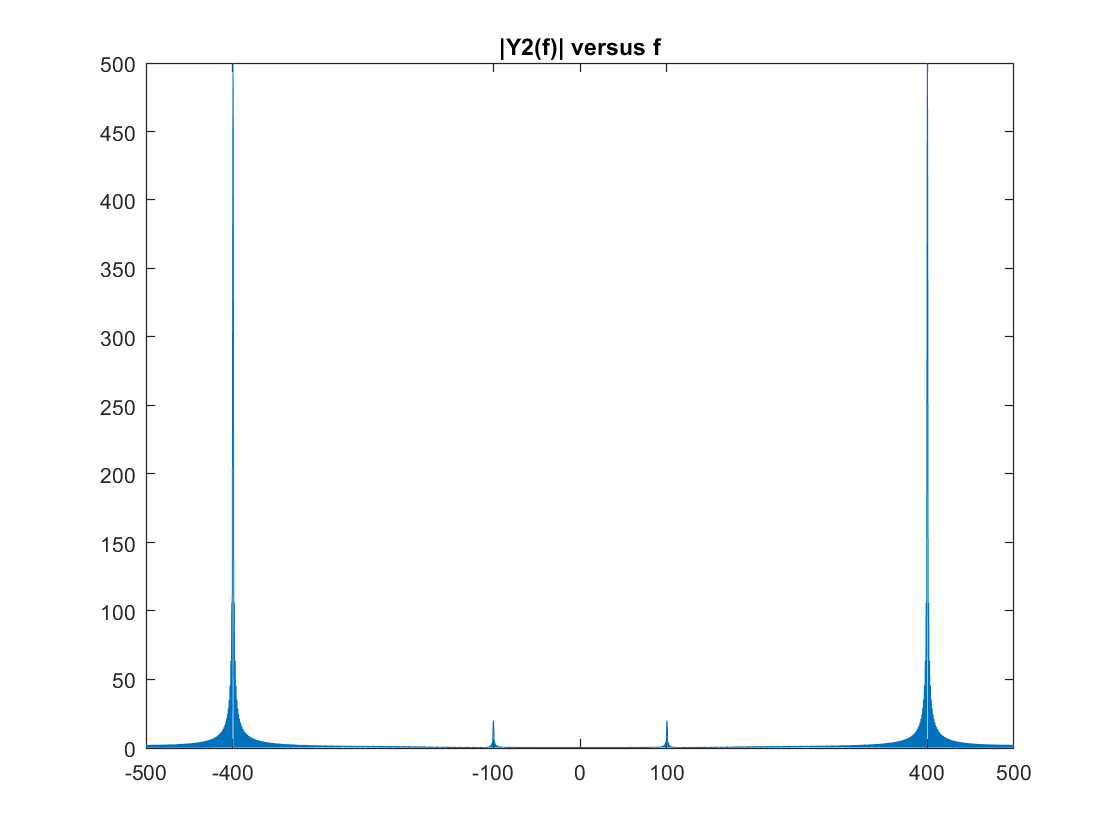

y2fftsh = fftshift(fft(y2,M));
plot(freq, abs(y2fftsh)); 
ax = gca;
ax.XTick = [-500 -400 -100 0 100 400 500];
title('|Y2(f)| versus f')